# **数学实验三**

#### 1.搜集某个地区（国、省、市）的近10年人口数据

#### （1）保留时间上最近的两个数据做检验，根据其余数据分别用 Malthus 模型和 Logistic 模型拟合参数与初值，并计算模型在上述两个用于检验的数据上的误差。

#### （2）根据样本数据散点图特点，分析采用 Malthus 和 Logistic 两个经典模型对搜集的数据建模是否合适？如不合适，请给出具体改进的模型，结合数值解给出合理解释。

#### 解：（1）

- 读取数据并处理：

% 读取 Excel 表格数据,得到数据规模
data = xlsread('广东省人口.xlsx', 'Sheet1');
L=size(data);
length=L(1,1);
% 用于预测和绘图的数据：
recent_p = data(end-1:end,2);
years = data(:,1);
years_t = years-2011;
population=data(:,2);
% 用于拟合参数和初值的数据
y = data(1:(length-2),1);%年份
t = y-2011;
p = data(1:(length-2),2);%单位：万人

- Malthus模型拟合，其方程为$\frac {d p}{d t}=r p , p_0=p(0)$，其解为$p(t)=p_0 e^{rt}$：

% 设置x=ln(p)，方便线性拟合
x = log(p);
P1 = polyfit(t, x, 1);
% Malthus模型拟合
malthus_x= polyval(P1, years_t);%得到拟合曲线的x值
malthus_p=exp(malthus_x);%转换为人口数

- Logistic模型拟合，其方程为$\frac {d p}{d t}=r p (1-\frac {p}{ p_m}), p_0=p(0)$，其解为$p(t)=\frac{p_m}{1+(\frac{p_m} {p_0} -1 ）e^{-rt}}$：

% 求解微分方程验证
syms p_s(tt) r_data1 pm p0; % 声明符号变量
eqn = diff(p_s) == r_data1*p_s*(1-p_s/pm); % 构建常微分方程
logistic_sol = dsolve(eqn, p_s(0) == p0) % 求解常微分方程

$$logistic\_sol = -\frac{\mathrm{pm}}{{\mathrm{e}}^{\log\left(1-\frac{\mathrm{pm}}{p_{0}}\right)-r_{\mathrm{data1}}\,\mathrm{tt}}-1}$$

%拟合
p0=p(1);%人口初值
P=@(b,t) b(1)./(1+(exp(-b(2).*t).*(b(1)./p0-1)));%pm=b(1),r=b(2)
b0=[10000,0.9];%初始参数
beta=nlinfit(t',p',P,b0);%拟合系数
pm=beta(1,1)

pm = 1.5037e+04

r_data1=beta(1,2)

r_data1 = 0.0844

%根据拟合参数得到函数及函数值
logistic_func=@(t)  pm/(1+(exp(-r_data1*t)*(pm/p0-1))) ;
logistic_p=zeros(11,1);
for i=1:11
    logistic_p(i,1)=logistic_func(years_t(i,1));
end

- 绘制拟合曲线和散点图

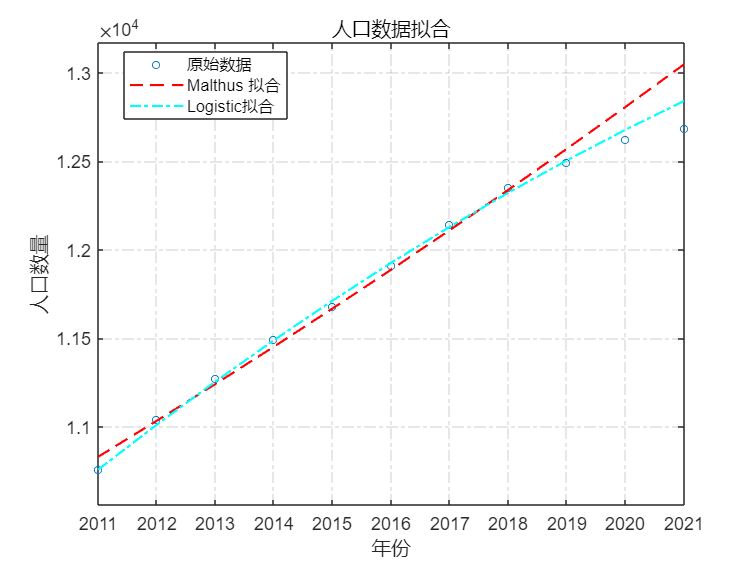

figure;
%画图
plot(years, population, 'o', 'MarkerSize', 4);
hold on;
P1=plot(years,malthus_p, 'r--');
P2=plot(years,logistic_p,'c-.');
%设置线宽
P1.LineWidth =1.2;P2.LineWidth =1.2;
%打开网格
grid on;
set(gca, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '-.');
%设置图例，标签等
legend('原始数据', 'Malthus 拟合','Logistic拟合');
xlabel('年份');
ylabel('人口数量');
title('人口数据拟合');
legend("Position",[0.16393,0.78984,0.21607,0.11905])
%设置显示范围
xlim([2011 2021])
ylim([10557 13171])

- 计算误差：

% 计算Malthus模型在最近两个数据点上的误差
malthus_recent=malthus_p(10:11,1);
malthus_error = malthus_recent-recent_p;
malthus_error=abs(malthus_error./recent_p);
disp(malthus_error);

    0.0144
    0.0286



% 计算Logistic模型在最近两个数据点上的误差
logistic_recent=logistic_p(10:11,1);
logistic_error = logistic_recent-recent_p;
logistic_error=abs(logistic_error./recent_p);
disp(logistic_error);

    0.0042
    0.0123



#### （2）

结论：Malthus模型不太合适，Logistic模型比较合适

#### 2. 针对 COVID-19疫情，搜集某个地区（省、市）的疫情相关数据（可以通过各地卫健委网站获取每日疫情数据）：

#### （1） 用经典的 SIR模型，根据搜集的数据尝试用多种手段确定模型参数。

#### （2） 如果经典模型所得结果误差较大，请分析原因，建立适合当地疫情发展规律的传染病模型。重新估计模型参数，并分析模型误差情况。

#### （3）考虑加入一些可行的干预措施，并分析其对新冠疫情的影响。